clc, clearvars;
kp = -750; ki = -100; kd = 1;  
R = 0.3;
L = 0.45;
l = 0.8;
M = 16;
m = 80;
kT = 0.75;
kbemf = 0.75;
r_a = 1.5;
c1 = 0.1;
c2 = 0.1;
g = 9.81;
alpha = kT/r_a;
beta = (kT*kbemf)/(R*r_a);
J = m*l^2 + M*L^2;
A = (M*g*L + m*g*l)/J;
B = beta/J;
C = alpha/J;
E = m*g/J;
F = c1/J;
G = alpha/(R*(M+m));
H = (beta/R + c2)/(M + m);
s = tf('s');
g1 = G/(s*(s+H));
N3 = (B*G-(s+H)*C);
N4 = E;
D1 = (s^2+F*s-A);
D2 = (s+H);
G3 = N3/(D1*D2);
G4 = N4/D1;
N3/(D1*D2);

## For charac equations of the outputs 

O = D1*D2; %%Denominator of theeta(s)/V(s)
s*(R+M)*R+beta+c2*R; %% Denominator of theeta(s)/d(s)
s+H; %% Denominator of X(s)/V(s)

## For the R-H array 

u = 72.5632*s^3 - 89.7839*s - 14.4*ki*s - 0.64*kp*s - 0.64*kd*s^2 - 14.4*kd*s^3 - 14.4*kp*s^2 - 2034.0736*s^2 - 0.64*ki + 1567.872*s^4  %%D1D2 = (s^2*J+c1*s-(M*g*L))*(s*R*(M+m)+beta+c2*R)+(alpha*beta-alpha*(s*R*(M+m)+beta+c2*R)*(kp+ki/s+kd*s))

u =
 
  1568 s^4 + 58.16 s^3 + 8765 s^2 + 1830 s + 64
 
Continuous-time transfer function.
Model Properties


## For root locus

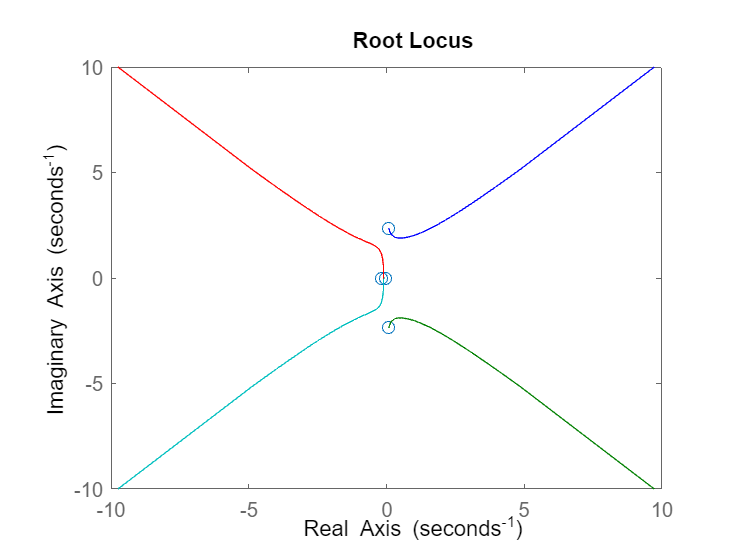

rlocus(u);